Final Project - Preproccessin - MFCC - Currently no data augmentation

clear; close all; %fresh start

%USER SELECT
device = 0; %0=mac,1=windows
state = 1;%0=disable,1=enable saving figure

tic %start timer

save_file_path = getFP("MFCC_mat",device) %change string here - output folder

save_file_path = "/Users/daniel/Desktop/Dissertation/CODE/MFCC_mat"

audio_folder_path = getFP("Audio files/ESC-50-master",device) %change string here - input folder

audio_folder_path = "/Users/daniel/Desktop/Dissertation/CODE/Audio files/ESC-50-master"


% Set up the audio datastore
ADS = audioDatastore(audio_folder_path, 'FileExtensions', '.wav', 'IncludeSubfolders', true);

fprintf("Load Files List,\nElapsed time = %.06f [sec]",toc) %load files list

Load Files List,
Elapsed time = 0.070014 [sec]


%pre allocate memory for figure
fs=0;

% Loop through each file in the audio datastore = ads
while hasdata(ADS)
    % Read the audio file
    [audioData, info] = read(ADS);

    % Get the original filename %[path,fileName,extention]
    [~, fileName, ~] = fileparts(info.FileName);

    % Perform MFCC
    [coeffs,delta,deltaDelta,~] = mfcc(audioData, info.SampleRate,"LogEnergy","Ignore");

    %Group Coeff + Delta + DeltaDelta into 1 matrix
    grouped_data = {coeffs,delta,deltaDelta};
    c_d_dd = cat(3,grouped_data{:});

    save(fullfile(save_file_path, [fileName, '.mat']),'c_d_dd')
end

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

    20

    21

    22

    23

    24

    25

    26

    27

    28

    29

    30

    31

    32

    33

    34

    35

    36

    37

    38

    39

    40

    41

    42

    43

    44

    45

    46

    47

    48

    49

    50

    51

    52

    53

    54

    55

    56

    57

    58

    59

    60

    61

    62

    63

    64

    65

    66

    67

    68

    69

    70

    71

    72

    73

    74

    75

    76

    77

    78

    79

    80

    81

    82

    83

    84

    85

    86

    87

    88

    89

    90

    91

    92

    93

    94

    95

    96

    97

    98

    99

   100

   101

   102

   103

   104

   105

   106

   107

   108

   109

   110

   111

   112

   113

   114

   115

   116

   117

   118

   119

   120

   121

   122

   123

   124

   125

   126



Finished Importing/Exporting,
Elapsed time = 49.030240 [sec]

data = 685×869×3 uint8 array
data(:,:,1) =

   255    55    55   175    23    23    91    91   123   123    35     0     0    31    31     0     0    39     0     0    43    43    31    31     0     0     0     0     0     0     0     0     0     0    11    11     0     0    91   115   115    83    83     0     0    47    71    71   127   127    35    35   119    23    23    75    75   207   207   255   255   255   183   183    91   139   139   111   111   243   243   255   255   255    79    79    43    43   199   195   195   171   171   255   255   255   255   255   227   227   235   235   255   119   119   147   147   135   135   211   119   119   119   119   103   103   119   255   255   123   123   103   103   131    19    19    15    15    83    83    35    83    83   123   123    79     0     0     0     0    83    83    39   199   199    11    11     0     0     3     0     0     7     7     0     0   107    95    95     0     0     0     0     0     0     0    75    75   231  

save_file_path = "/Users/daniel/Desktop/Dissertation/CODE/MFCC_png"

audio_folder_path = "/Users/daniel/Desktop/Dissertation/CODE/Audio files"

fs = 44100

coeff_og =     3.0730   -7.2974    2.5181    0.2143    0.3551   -0.5358   -0.1127   -0.6987   -0.1387    0.0977   -0.2939   -0.0113   -0.1135   -0.1944
    3.5011   -7.2109    2.4402    0.0108    0.3201   -0.5374   -0.0555   -0.5249   -0.3946   -0.1757   -0.5605   -0.3705   -0.1247    0.0365
    3.5799   -6.7254    2.7285   -0.1509    0.2829   -0.5279   -0.3705   -0.6484   -0.1336   -0.1777   -0.6146   -0.5026   -0.4417   -0.2566
    3.4017   -6.3713    2.8611   -0.2598    0.4487   -0.4058   -0.1199   -0.2057   -0.1254    0.0689   -0.2183   -0.0724   -0.0159   -0.1227
    3.2982   -6.3534    2.6341   -0.6363    0.2385   -0.6553   -0.0396   -0.0410    0.1002    0.0468   -0.0733    0.0498    0.2832   -0.0616
    3.3033   -6.3622    2.7506   -0.1655    0.0792   -0.5499    0.3185    0.0547    0.1653   -0.0156   -0.2345   -0.1810    0.3759   -0.2331
    3.5966   -6.3519    2.6797   -0.2970    0.1452   -0.5813   -0.2289   -0.2226    0.2010   -0.0730   -0.3155   -0.1274    0.0281   -0.3255
  

win_length = 1323

coeff_duplicated =     3.0730   -7.3622    2.5342    0.2189    0.3683   -0.5314   -0.1038   -0.7121   -0.1504    0.0913   -0.2875   -0.0004   -0.1146   -0.2025
    3.5011   -7.2900    2.4370    0.0171    0.3393   -0.5260   -0.0459   -0.5209   -0.4283   -0.1968   -0.5756   -0.3845   -0.1180    0.0467
    3.5799   -6.7913    2.7312   -0.1561    0.2772   -0.5322   -0.3868   -0.6608   -0.1289   -0.1847   -0.6078   -0.5151   -0.4698   -0.2711
    3.4017   -6.4360    2.8734   -0.2536    0.4633   -0.3996   -0.1227   -0.1989   -0.1367    0.0607   -0.2264   -0.0737   -0.0130   -0.1096
    3.2982   -6.4353    2.6331   -0.6570    0.2460   -0.6540   -0.0488   -0.0425    0.1026    0.0579   -0.0559    0.0522    0.2720   -0.0627
    3.3033   -6.4462    2.7643   -0.1350    0.0718   -0.5547    0.3351    0.0666    0.1780   -0.0111   -0.2393   -0.1844    0.3842   -0.2380
    3.5966   -6.4287    2.6669   -0.2994    0.1618   -0.5712   -0.2351   -0.2410    0.1825   -0.0800   -0.2978   -0.0994    0.0432   -0

delta_error = -42.7762

aFE =   audioFeatureExtractor with properties:

   Properties
                     Window: [1323×1 double]
              OverlapLength: 882
                 SampleRate: 44100
                  FFTLength: []
    SpectralDescriptorInput: 'melSpectrum'
        FeatureVectorLength: 13

   Enabled Features
     mfcc

   Disabled Features
     linearSpectrum, melSpectrum, barkSpectrum, erbSpectrum, mfccDelta, mfccDeltaDelta
     gtcc, gtccDelta, gtccDeltaDelta, spectralCentroid, spectralCrest, spectralDecrease
     spectralEntropy, spectralFlatness, spectralFlux, spectralKurtosis, spectralRolloffPoint, spectralSkewness
     spectralSlope, spectralSpread, pitch, harmonicRatio, zerocrossrate, shortTimeEnergy


   To extract a feature, set the corresponding property to true.
   For example, obj.mfcc = true, adds mfcc to the list of enabled features.


features =   -25.9931    5.5773   -1.6690    0.7536   -1.4530   -0.3661   -2.3407    0.0382   -1.3543   -0.1964   -0.5267    0.4536   -0.0733
  -25.7012    5.4308   -1.6028    0.4999   -1.2740   -0.5568   -2.1930   -0.2852   -1.3615   -0.3719   -0.7182    0.2478   -0.0002
  -24.9188    6.0298   -1.0246    0.3891   -0.9291   -0.3395   -1.5642   -0.1885   -1.0262    0.0460   -0.2266    0.5419    0.0249
  -24.3737    6.3783   -0.9812    0.5601   -0.6314    0.3285   -1.3631    0.1091   -0.5652    0.2052   -0.3091    0.2731    0.0484
  -24.4876    6.4736   -1.4389    0.3409   -0.8114    0.4838   -1.3479    0.4005   -0.3706    0.2621   -0.2618    0.2564   -0.3073
  -24.4859    6.7725   -1.1506    1.1040   -0.8375    0.2423   -1.1096    0.7475   -0.1535    0.3531   -0.2938   -0.0053   -0.3320
  -24.7802    7.1230   -1.6389    0.7090   -1.0992   -0.0159   -1.3417    0.2619   -0.6703    0.4088    0.0663    0.3815   -0.2392
  -24.7353    7.4837   -1.1746    0.7886   -0.9366    0.2102   -1.3247  

idx = struct with fields:
    mfcc: [1 2 3 4 5 6 7 8 9 10 11 12 13]


numHops1 = 498

numFeaturesFile1 = 13

numChanelsFile1 = 1

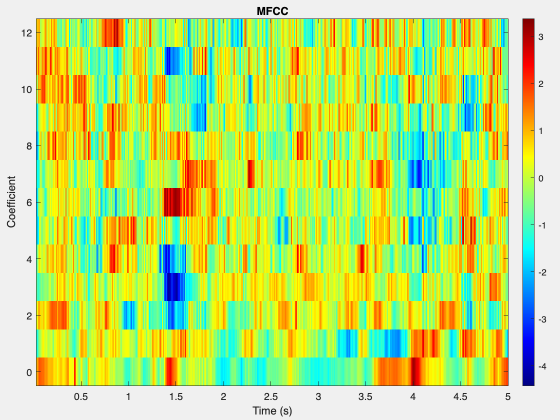


%end timer - see how long it took
fprintf("Finished Importing/Exporting,\nElapsed time = %.06f [sec]",toc) %load files list

function savefig(figur,fileName,device,state)
if state

    if device   %windows
        filePath = getFP(fileName,device);
        fullPath = filePath + "\MFCC\" + fileName;
        saveas(figur,fullPath)
    else        %mac
        filePath = getFP(fileName,device);
        fullPath = filePath + "/MFCC/" + fileName;
        saveas(figur,fullPath)
    end
end
        %fprintf('%s\n',fullPath);
end

function fp = getFP(fileName,device)
if device
    %windows-> device=1
    filePath = matlab.desktop.editor.getActiveFilename;
    filePath(find(filePath=='\',1,'last'):end) = [];
    fullPath = filePath + "\" + fileName;
    fp = fullPath;
else
    %mac-> device=0
    filePath = matlab.desktop.editor.getActiveFilename;
    filePath(find(filePath=='/',1,'last'):end) = [];
    fullPath = filePath + "/" + fileName;
    fp = fullPath;
end
%fprintf('%s\n',fullPath);
end
